# 論文の実装~Algorithm 1~

## システムのダイナミクス

A = [-1 2; 2.2 1.7];
B = [2; 1.6]

B =     2.0000
    1.6000


C = [1 2];

sys = ss(A, B, C, [], 1)


sys =
 
  A = 
        x1   x2
   x1   -1    2
   x2  2.2  1.7
 
  B = 
        u1
   x1    2
   x2  1.6
 
  C = 
       x1  x2
   y1   1   2
 
  D = 
       u1
   y1   0
 
サンプル時間:  1 seconds
離散時間状態空間モデル。



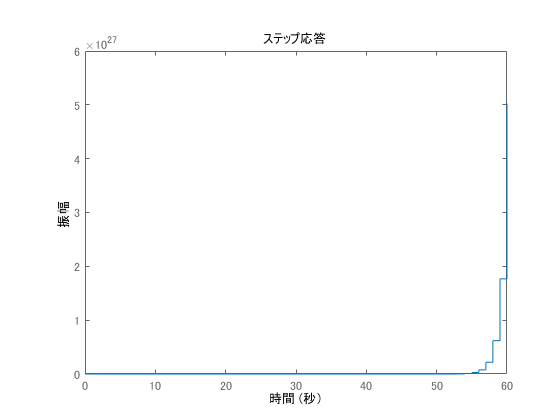

step(sys)

## 学習パラメータ

F = -1;
Q = 6;
R = 1;
gamma = 0.8;
learningFreq = 21;

K_0 = [0.3 1.3 0.75];
x_0 = [5; -5];
r_0 = [5];
X_0 = [x_0; r_0];

## その他変数宣言

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];
Q1 = C1'*Q*C1;

## 学習

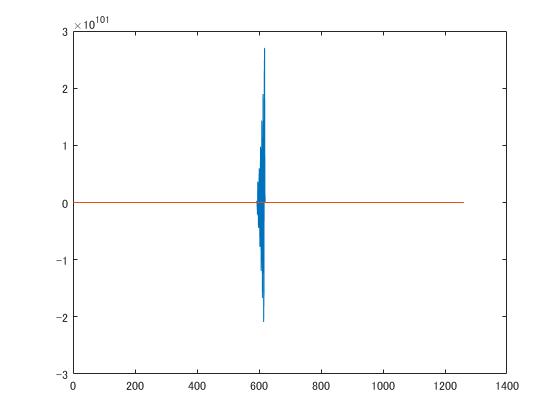

% 初期化
X = X_0;
X_old = X_0;
K1 = K_0;
% K1 = [-0.1898 1.0085 -0.0640];
sampleNum = 0;
yBuffer = zeros(learningFreq, 1);
hBuffer = zeros(learningFreq, (length(X))*((length(X))+1)/2);

yList = [C*x_0];
rList = [r_0];


for i = 1 : 60*21
    if (i > 1)
        if (sampleNum >= learningFreq)
            % 方策評価
%             theta = (hBuffer'*hBuffer)\hBuffer'*yBuffer;
            theta = pinv(hBuffer)*yBuffer;

            
            n = length(X);
            idx = 1;
            for r = 1:n
                for c = r:n
                    Phat(r,c) = theta(idx);
                    idx = idx + 1;
                end
            end
            P  = 1/2*(Phat+Phat');
            
            % 方策改善
            K1 = (R+gamma*B1'*P*B1)\gamma*B1'*P*T;
            
            sampleNum = 0;
            yBuffer = zeros(learningFreq, 1);
            hBuffer = zeros(learningFreq, (length(X))*((length(X))+1)/2);
        else
            sampleNum = sampleNum + 1;
            
            y = X_old'*(Q1+K1'*R*K1)*X_old;
            h1 = computeQuadraticBasis(X_old);
            h2 = computeQuadraticBasis(X);
            h = h1-gamma*h2;
            yBuffer(sampleNum) = y;
            hBuffer(sampleNum, :) = h;
        end
    end
    
    % 行動決定
    u = -K1*X+2*randn(1,1);
    
    % 状態遷移
    X_old = X;
    X = T * X + B1 * u;
    y = C * X(1:2);
    
    r = X(3);
    yList = [yList; y];
    rList = [rList; r];
end

plot(yList);
hold on;
plot(rList);